clc
clear
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

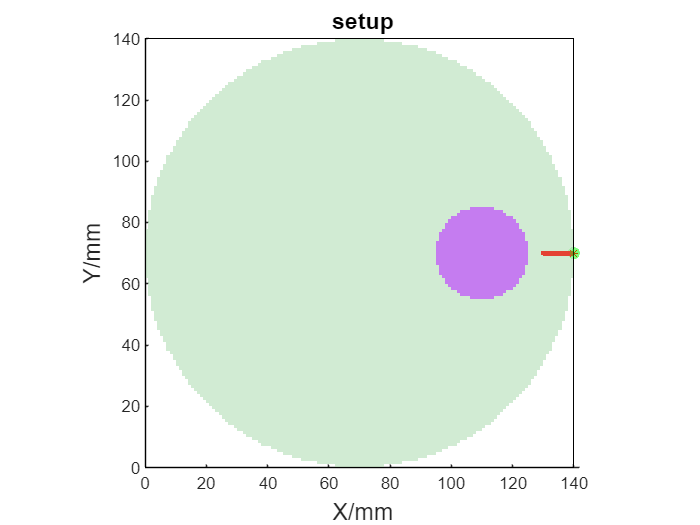

%% 2D CSF simulation main simulation
save_flag = 0; % 0 is not saving any picture
clear cfg_csf;

% % % % ------------general setting---------
cfg_csf.nphoton = 1e7;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
% cfg_csf.maxdetphoton = cfg_csf.nphoton;
cfg_csf.maxdetphoton = 1e6;
brain_radius = 70;
cfg_csf.vol = permute(uint8(zeros([2*brain_radius,2*brain_radius])), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 3e-9;
cfg_csf.tstep = 5e-11;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
BinFlag = ((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2; % the bin value of each timebin
source_angle = linspace(-pi/3,0,9)'; % angle range of source angle
det_angle = linspace(-pi/3,pi/3,17)'; % angle range of det angle
% source_angle = linspace(-pi/3,0,5)'; % angle range of source angle
% det_angle = linspace(-pi/3,pi/3,9)'; % angle range of det angle
% % % % -----------general setting end------------

% % % % build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius];
[grid_z,grid_y] = ndgrid(linspace(2*brain_radius-0.5,0.5,2*brain_radius),linspace(0.5,2*brain_radius-0.5,2*brain_radius));

dmua_tumour = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua_tumour 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [49 49+3];

for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 1;
            case D_from_center(i,j)<=brain_radius
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% % % % source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  0;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  0; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
% % % %  det set end


vol_background = cfg_csf.vol; % keep the background of the vol;

tumour_position = 40;

% % % % ----------set tumour-------------------
tuc_pos = [tumour_position 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end
% % % % ----------set tumour end-------------------

% set tumour mask
tumour_mask = squeeze(cfg_csf.vol);
tumour_mask(find(tumour_mask~=3))=0;
tumour_mask(find(tumour_mask==3))=1;
tumour_mask = rot90(tumour_mask); % so the tumour_mask here is already rotted
% figure;imagesc(tumour_mask);

% % % % ----------show the setup
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);
% figure,imagesc(double(squeeze(cfg_csf.vol)))
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

[~, detpt_csf, ~, seeds] = mcxlab(cfg_csf);

Launching MCXLAB - Monte Carlo eXtreme for MATLAB & GNU Octave ...
Running simulations for configuration #1 ...
mcx.nphoton=1e+07;
mcx.gpuid='11';
mcx.workload=<<2>>;
mcx.autopilot=1;
mcx.maxdetphoton=1e+06;
mcx.dim=[1 140 140];
mcx.mediabyte=1;
mcx.tstart=0;
mcx.tend=3e-09;
mcx.tstep=5e-11;
mcx.debuglevel=4;
mcx.unitinmm=1;
mcx.issrcfrom0=1;
mcx.medianum=4;
mcx.srcpos=[0 140 70 1];
mcx.srcdir=[0 -1 -0 0];
mcx.srctype='pencil';
mcx.detnum=1;
###############################################################################
#                      Monte Carlo eXtreme (MCX) -- CUDA                      #
#          Copyright (c) 2009-2025 Qianqian Fang <q.fang at neu.edu>          #
#                https://mcx.space/  &  https://neurojson.io                  #
#                                                                             #
# Computational Optics & Translational Imaging (COTI) Lab- http://fanglab.org #
#   Department of Bioengineering, Northeastern University, Boston, MA, USA

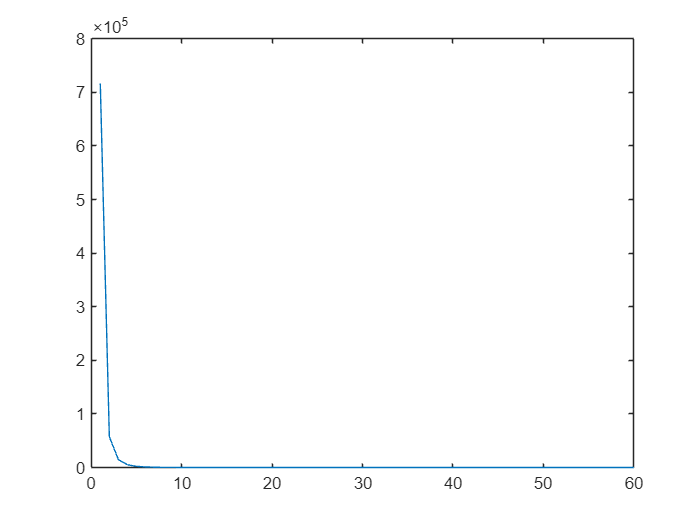

tpsf = mcxdettpsf(detpt_csf,1,cfg_csf.prop,[cfg_csf.tstart, cfg_csf.tend,cfg_csf.tstep]);
plot(tpsf)